# Display AircraftData

clear variables; close all; clc;

## Global declarations

% Disable warnings to avoid annoying messages for interpolating functions
warning ('off','all');

load AircraftData.mat

## Plot CL

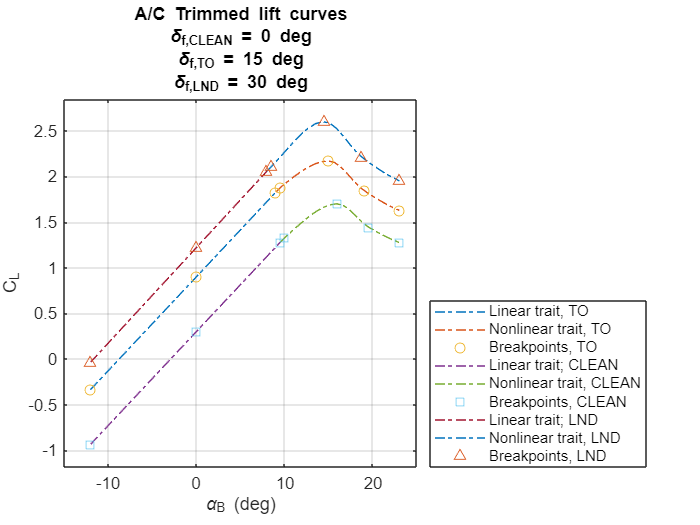

figure
% TO
plot(convang(AircraftData.Aerodynamics.Interp.v_AoA_TO_1,'rad','deg'), AircraftData.Aerodynamics.Interp.v_CL_TO_1, '-.')
hold on
plot(convang(AircraftData.Aerodynamics.Interp.v_AoA_TO_2,'rad','deg'), AircraftData.Aerodynamics.Interp.v_CL_TO_2, '-.', 'MarkerSize', 4)
plot( ... % breakpoints
    convang( ...
        [AircraftData.Aerodynamics.Interp.v_AoA_TO_bp_1, AircraftData.Aerodynamics.Interp.v_AoA_TO_bp_2],'rad','deg'), ...
    [AircraftData.Aerodynamics.Interp.v_CL_TO_bp_1, AircraftData.Aerodynamics.Interp.v_CL_TO_bp_2], ...
    'o', 'MarkerSize',6)

% CLEAN
plot( ...
    convang( ...
        AircraftData.Aerodynamics.Interp.v_AoA_CLEAN_1,'rad','deg'), ...
    AircraftData.Aerodynamics.Interp.v_CL_CLEAN_1, '-.')
plot( ...
    convang( ...
        AircraftData.Aerodynamics.Interp.v_AoA_CLEAN_2,'rad','deg'), ...
    AircraftData.Aerodynamics.Interp.v_CL_CLEAN_2, '-.', 'MarkerSize', 4)
plot( ... % breakpoints
    convang( ...
        [AircraftData.Aerodynamics.Interp.v_AoA_CLEAN_bp_1, AircraftData.Aerodynamics.Interp.v_AoA_CLEAN_bp_2],'rad','deg'), ...
    [AircraftData.Aerodynamics.Interp.v_CL_CLEAN_bp_1, AircraftData.Aerodynamics.Interp.v_CL_CLEAN_bp_2], ...
    's', 'MarkerSize',6)

% LND
plot( ...
    convang( ...
        AircraftData.Aerodynamics.Interp.v_AoA_LND_1,'rad','deg'), ...
    AircraftData.Aerodynamics.Interp.v_CL_LND_1, '-.')
plot( ...
    convang( ...
        AircraftData.Aerodynamics.Interp.v_AoA_LND_2,'rad','deg'), ...
    AircraftData.Aerodynamics.Interp.v_CL_LND_2, '-.', 'MarkerSize', 4)
plot( ... % breakpoints
    convang( ...
        [AircraftData.Aerodynamics.Interp.v_AoA_LND_bp_1, AircraftData.Aerodynamics.Interp.v_AoA_LND_bp_2],'rad','deg'), ...
    [AircraftData.Aerodynamics.Interp.v_CL_LND_bp_1, AircraftData.Aerodynamics.Interp.v_CL_LND_bp_2], ...
    '^', 'MarkerSize',6)

legend({ ...
    'Linear trait, TO','Nonlinear trait, TO','Breakpoints, TO', ...
    'Linear trait; CLEAN','Nonlinear trait, CLEAN','Breakpoints, CLEAN', ...
    'Linear trait; LND','Nonlinear trait, LND','Breakpoints, LND' ...
    },'Location','southeastoutside')

axis padded
xlabel("\alpha_B (deg)")
ylabel("C_{L}")
title({'A/C Trimmed lift curves', '\delta_{f,CLEAN} = 0 deg', '\delta_{f,TO} = 15 deg', '\delta_{f,LND} = 30 deg'})
grid on
hold off

### Check the global function for CL_TO

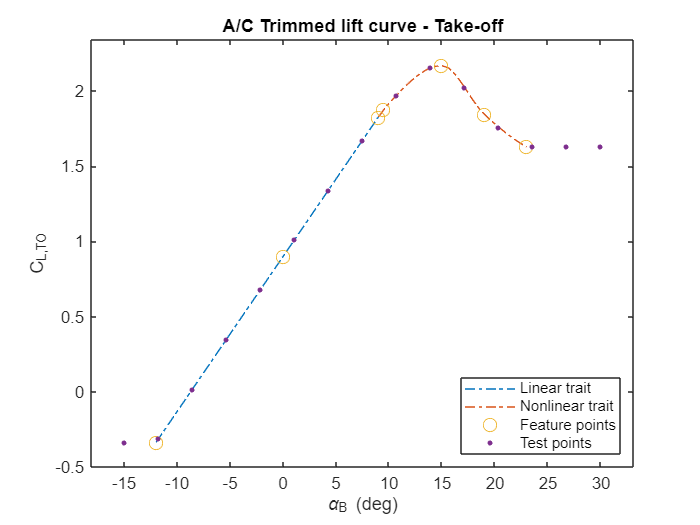

v_AoA_TO_g = convang(linspace(-15, 30, 15),'deg','rad');
v_CL_TO_g = zeros(1, length(v_AoA_TO_g));
for k=1:length(v_AoA_TO_g) 
    v_CL_TO_g(k) = f_CL_TO(AircraftData, v_AoA_TO_g(k)); 
end

figure
plot(convang(AircraftData.Aerodynamics.Interp.v_AoA_TO_1,'rad','deg'), AircraftData.Aerodynamics.Interp.v_CL_TO_1, '-.')
hold on
plot(convang(AircraftData.Aerodynamics.Interp.v_AoA_TO_2,'rad','deg'), AircraftData.Aerodynamics.Interp.v_CL_TO_2, '-.', 'MarkerSize', 4)
plot(convang([AircraftData.Aerodynamics.Interp.v_AoA_TO_bp_1, AircraftData.Aerodynamics.Interp.v_AoA_TO_bp_2],'rad','deg'), [AircraftData.Aerodynamics.Interp.v_CL_TO_bp_1, AircraftData.Aerodynamics.Interp.v_CL_TO_bp_2], 'o', 'MarkerSize', 8)

xlabel("\alpha_B (deg)")
ylabel("C_{L,TO}")
title("A/C Trimmed lift curve - Take-off")

plot(convang(v_AoA_TO_g,'rad','deg'), v_CL_TO_g, '.', 'MarkerSize',9)

legend({'Linear trait','Nonlinear trait','Feature points','Test points'},'Location','southeast')
axis padded
hold off

### Plot CL (2/n)

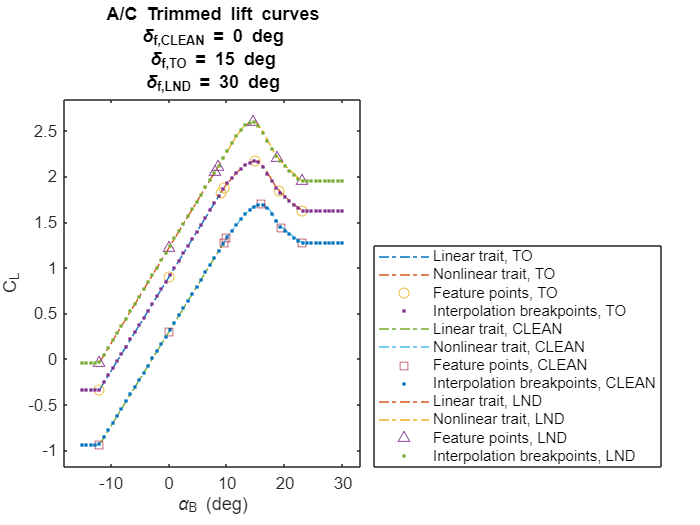

figure
% TAKE-OFF
plot( ...
    convang(AircraftData.Aerodynamics.Interp.v_AoA_TO_1,'rad','deg'), ...
    AircraftData.Aerodynamics.Interp.v_CL_TO_1, '-.')
hold on
plot( ...
    convang(AircraftData.Aerodynamics.Interp.v_AoA_TO_2,'rad','deg'), ...
    AircraftData.Aerodynamics.Interp.v_CL_TO_2, '-.', 'MarkerSize', 4)
plot( ...
    convang( ...
        [AircraftData.Aerodynamics.Interp.v_AoA_TO_bp_1, AircraftData.Aerodynamics.Interp.v_AoA_TO_bp_2],'rad','deg'), ...
    [AircraftData.Aerodynamics.Interp.v_CL_TO_bp_1, AircraftData.Aerodynamics.Interp.v_CL_TO_bp_2], 'o', 'MarkerSize', 6)
plot( ...
    convang(AircraftData.Aerodynamics.Interp.AoA_Interp_TO,'rad','deg'), ...
    AircraftData.Aerodynamics.Interp.CL_Interp_TO, '.', 'MarkerSize',6)

% CLEAN
plot( ...
    convang(AircraftData.Aerodynamics.Interp.v_AoA_CLEAN_1,'rad','deg'), ...
    AircraftData.Aerodynamics.Interp.v_CL_CLEAN_1, '-.')
plot( ...
    convang(AircraftData.Aerodynamics.Interp.v_AoA_CLEAN_2,'rad','deg'), ...
    AircraftData.Aerodynamics.Interp.v_CL_CLEAN_2, '-.', 'MarkerSize', 4)
plot( ...
    convang([AircraftData.Aerodynamics.Interp.v_AoA_CLEAN_bp_1, AircraftData.Aerodynamics.Interp.v_AoA_CLEAN_bp_2],'rad','deg'), ...
    [AircraftData.Aerodynamics.Interp.v_CL_CLEAN_bp_1, AircraftData.Aerodynamics.Interp.v_CL_CLEAN_bp_2], 's', 'MarkerSize', 6)
plot( ...
    convang(AircraftData.Aerodynamics.Interp.AoA_Interp_CLEAN,'rad','deg'), ...
    AircraftData.Aerodynamics.Interp.CL_Interp_CLEAN, '.', 'MarkerSize',6)

% LND
plot( ...
    convang(AircraftData.Aerodynamics.Interp.v_AoA_LND_1,'rad','deg'), ...
    AircraftData.Aerodynamics.Interp.v_CL_LND_1, '-.')
plot( ...
    convang(AircraftData.Aerodynamics.Interp.v_AoA_LND_2,'rad','deg'), ...
    AircraftData.Aerodynamics.Interp.v_CL_LND_2, '-.', 'MarkerSize', 4)
plot( ...
    convang([AircraftData.Aerodynamics.Interp.v_AoA_LND_bp_1, AircraftData.Aerodynamics.Interp.v_AoA_LND_bp_2],'rad','deg'), ...
    [AircraftData.Aerodynamics.Interp.v_CL_LND_bp_1, AircraftData.Aerodynamics.Interp.v_CL_LND_bp_2], '^', 'MarkerSize', 6)
plot( ...
    convang(AircraftData.Aerodynamics.Interp.AoA_Interp_LND,'rad','deg'), ...
    AircraftData.Aerodynamics.Interp.CL_Interp_LND, '.', 'MarkerSize',6)

xlabel("\alpha_B (deg)")
ylabel("C_{L}")
title({'A/C Trimmed lift curves', '\delta_{f,CLEAN} = 0 deg', '\delta_{f,TO} = 15 deg', '\delta_{f,LND} = 30 deg'})

axis padded

legend({ ...
    'Linear trait, TO','Nonlinear trait, TO','Feature points, TO','Interpolation breakpoints, TO', ...
    'Linear trait, CLEAN','Nonlinear trait, CLEAN','Feature points, CLEAN','Interpolation breakpoints, CLEAN', ...
    'Linear trait, LND','Nonlinear trait, LND','Feature points, LND','Interpolation breakpoints, LND' ...
    },'Location','southeastoutside')
hold off

### CL database as f(alpha, delta_f)

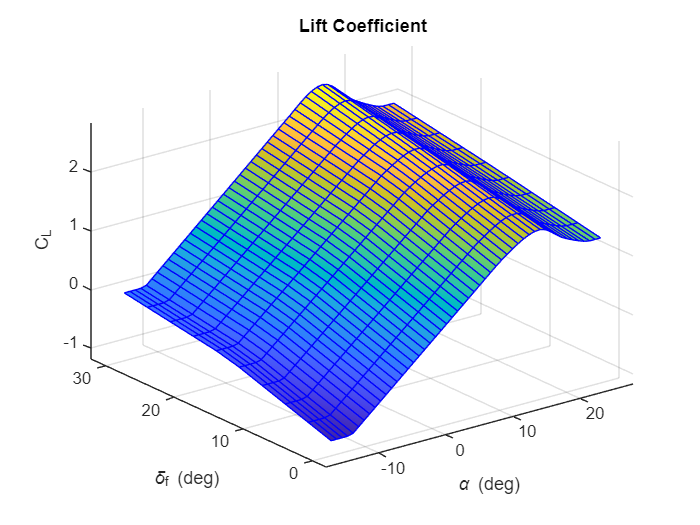

AircraftData.Aerodynamics.Interp.AoA_bp = AircraftData.Aerodynamics.Interp.AoA_Interp_TO;
AircraftData.Aerodynamics.Interp.delta_f_deg_bp = [AircraftData.Aerodynamics.delta_flap_deg_CLEAN, AircraftData.Aerodynamics.delta_flap_deg_TO, AircraftData.Aerodynamics.delta_flap_deg_LND];

AircraftData.Aerodynamics.Interp.CL_Interp = [ ...
    AircraftData.Aerodynamics.Interp.CL_Interp_CLEAN; 
    AircraftData.Aerodynamics.Interp.CL_Interp_TO; ...
    AircraftData.Aerodynamics.Interp.CL_Interp_LND];

% Plot the function: CL(alpha, delta_f)
[m_AoA, m_delta_f_deg] = meshgrid( ...
    AircraftData.Aerodynamics.Interp.AoA_bp, ...
    AircraftData.Aerodynamics.Interp.delta_f_deg_bp);
m_CL = AircraftData.Aerodynamics.Interp.CL_Interp;

vv_AoA = convang(linspace(-15, 25, 50),'deg','rad');
vv_delta_f_deg = linspace(0, 30, 10);
[mm_AoA, mm_delta_f_deg] = meshgrid(vv_AoA, vv_delta_f_deg);
mm_CL = interp2( ...
    m_AoA, m_delta_f_deg, m_CL, ...
    mm_AoA, mm_delta_f_deg, 'bilinear');

figure
s_CL = mesh(convang(mm_AoA,'rad','deg'), mm_delta_f_deg, mm_CL, 'EdgeColor', 'blue');
s_CL.FaceColor = 'interp';
title(['Lift Coefficient'])
xlabel('\alpha (deg)'); ylabel('\delta_f (deg)'); zlabel('C_L') 
axis padded

### Plot Thrust

Thrust is calculated by an interpolant function:


$$T=\frac{T}{T_0 }\left(M,h\right)\cdot T_0$$


#### TAKE-OFF

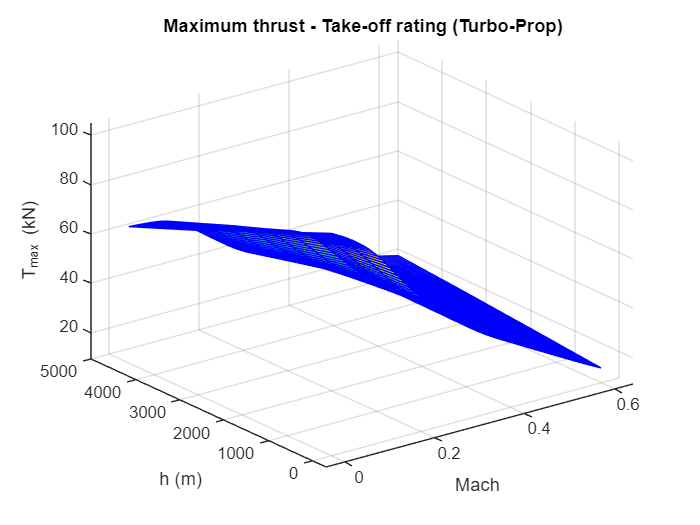

% Plot the function: (M,h) --> T/T0
[m_M_TO, m_h_ft_TO] = meshgrid( ...
    AircraftData.Propulsion.Interp.v_Mach_Thrust_TO_bp, ...
    AircraftData.Propulsion.Interp.v_h_ft_Thrust_TO_bp);
m_Tmax_TO = AircraftData.Propulsion.Thrust_0_TO * AircraftData.Propulsion.Interp.Thrust_Ratio_Interp_TO;

vv_Mach_Thrust_TO = linspace(0, 0.6, 70);
vv_h_ft_Thrust_TO = linspace(0, 15000, 10);
[mm_M_TO, mm_h_ft_TO] = meshgrid(vv_Mach_Thrust_TO, vv_h_ft_Thrust_TO);
mm_T_0_TO = interp2( ...
    m_M_TO, m_h_ft_TO, m_Tmax_TO, ...
    mm_M_TO, mm_h_ft_TO, 'bilinear');

figure
s_T_TO = mesh(mm_M_TO, convlength(mm_h_ft_TO,'ft','m'), mm_T_0_TO/1000., 'EdgeColor', 'blue');
s_T_TO.FaceColor = 'interp';
title(['Maximum thrust - Take-off rating (Turbo-Prop)'])
xlabel('Mach'); ylabel('h (m)'); zlabel('T_{max} (kN)') 
axis padded

#### CLIMB

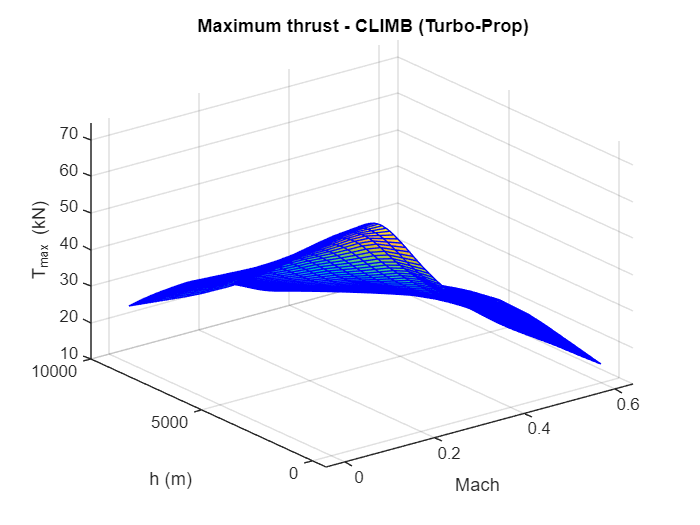

% Plot the function: (M,h) --> T/T0
[m_M_CLIMB, m_h_ft_CLIMB] = meshgrid( ...
    AircraftData.Propulsion.Interp.v_Mach_Thrust_CLIMB_bp, ...
    AircraftData.Propulsion.Interp.v_h_ft_Thrust_CLIMB_bp);
m_Tmax_CLIMB = AircraftData.Propulsion.Thrust_0_TO * AircraftData.Propulsion.Interp.Thrust_Ratio_Interp_CLIMB;

vv_Mach_Thrust_CLIMB = linspace(0, 0.6, 70);
vv_h_ft_Thrust_CLIMB = linspace(0, 30000, 15);
[mm_M_CLIMB, mm_h_ft_CLIMB] = meshgrid(vv_Mach_Thrust_CLIMB, vv_h_ft_Thrust_CLIMB);
mm_T_max_CLIMB = interp2( ...
    m_M_CLIMB, m_h_ft_CLIMB, m_Tmax_CLIMB, ...
    mm_M_CLIMB, mm_h_ft_CLIMB, 'bilinear');

figure
s_T_CLIMB = mesh(mm_M_CLIMB, convlength(mm_h_ft_CLIMB,'ft','m'), mm_T_max_CLIMB/1000., 'EdgeColor', 'blue');
s_T_CLIMB.FaceColor = 'interp';
title(['Maximum thrust - CLIMB (Turbo-Prop)'])
xlabel('Mach'); ylabel('h (m)'); zlabel('T_{max} (kN)') 
axis padded

#### CRUISE

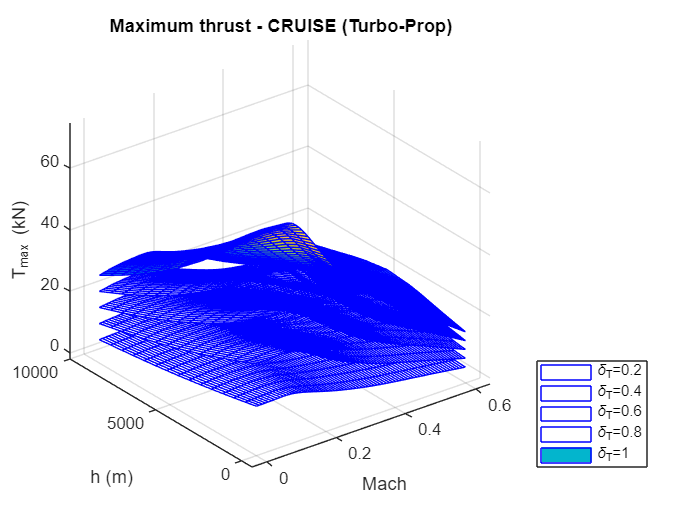

% Plot the function: (M,h,thr) --> T/T0
[m_throttle_CRUISE, m_M_CRUISE, m_h_ft_CRUISE] = ndgrid( ...
    AircraftData.Propulsion.Interp.v_Throttle_Thrust_CRUISE_bp, ...
    AircraftData.Propulsion.Interp.v_Mach_Thrust_CRUISE_bp, ...
    AircraftData.Propulsion.Interp.v_h_ft_Thrust_CRUISE_bp);

m_Tmax_CRUISE = AircraftData.Propulsion.Thrust_0_TO * AircraftData.Propulsion.Interp.Thrust_Ratio_Interp_CRUISE;

vv_throttle_Thrust_CRUISE = linspace(0.2, 1.0, 5);
vv_Mach_Thrust_CRUISE     = linspace(0, 0.6, 70);
vv_h_ft_Thrust_CRUISE     = linspace(0, 30000, 15);

[mm_throttle_CRUISE, mm_M_CRUISE, mm_h_ft_CRUISE] = ndgrid( ...
    vv_throttle_Thrust_CRUISE, vv_Mach_Thrust_CRUISE, vv_h_ft_Thrust_CRUISE);

mm_T_max_CRUISE = interpn( ...
    m_throttle_CRUISE, m_M_CRUISE, m_h_ft_CRUISE, m_Tmax_CRUISE, ...
    mm_throttle_CRUISE, mm_M_CRUISE, mm_h_ft_CRUISE, 'bilinear');

figure
s_T_CRUISE = mesh( ...
    squeeze(mm_M_CRUISE(1,:,:)), ...
    squeeze(convlength(mm_h_ft_CRUISE(1,:,:),'ft','m')), ...
    squeeze(mm_T_max_CRUISE(1,:,:))/1000., ...
    'EdgeColor', 'blue');
hold on
lbls_legend{1} = sprintf('\\delta_T=%s',num2str(vv_throttle_Thrust_CRUISE(1)));
for kThr=2:length(vv_throttle_Thrust_CRUISE)
    lbls_legend{kThr} = sprintf('\\delta_T=%s',num2str(vv_throttle_Thrust_CRUISE(kThr)));
    s_T_CRUISE = mesh( ...
        squeeze(mm_M_CRUISE(kThr,:,:)), ...
        squeeze(convlength(mm_h_ft_CRUISE(kThr,:,:),'ft','m')), ...
        squeeze(mm_T_max_CRUISE(kThr,:,:))/1000., ...
        'EdgeColor', 'blue');
end

legend(lbls_legend,'Location','southeastoutside')

s_T_CRUISE.FaceColor = 'interp';
title(['Maximum thrust - CRUISE (Turbo-Prop)'])
xlabel('Mach'); ylabel('h (m)'); zlabel('T_{max} (kN)') 
axis padded
hold off

### Thrust Specific Fuel Consumption, TSFC - original units: lbf/(lbf*hr) -> SI units: (9.81/3600) * kg/(N*s)

% Use the same break-points that define thrust interpolation 
% v_Mach_Thrust_TO_bp = linspace(0, 0.6, 52);
% v_h_ft_Thrust_TO_bp = [0 5000 10000 15000];

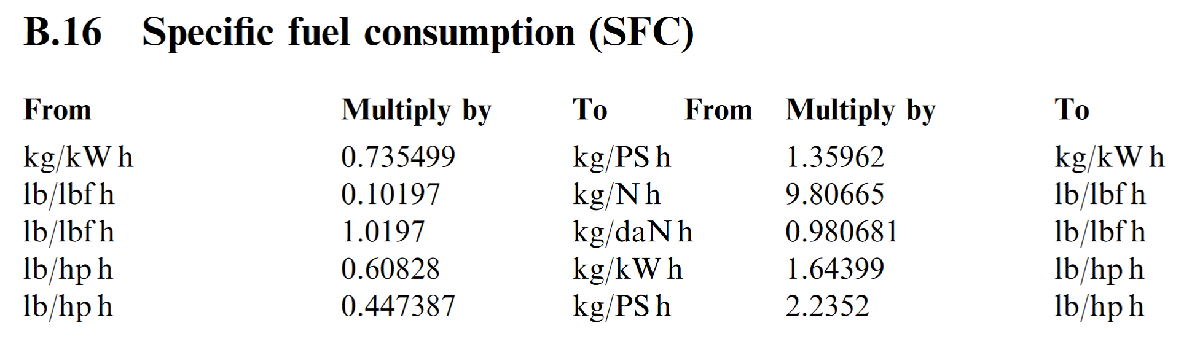

#### TAKE-OFF

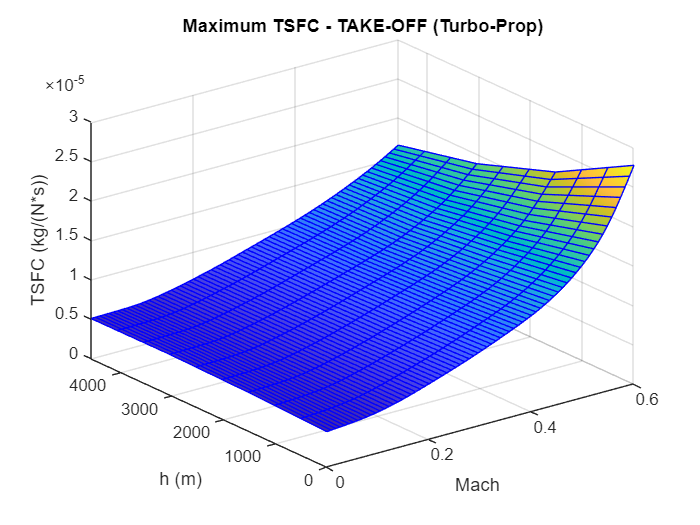

m_TSFC_Interp_TO = AircraftData.Propulsion.Interp.TSFC_Interp_TO; % original data in lb/(lbf*hr)

mm_TSFC_SI_TO = interp2( ...
    m_M_TO, m_h_ft_TO, AircraftData.Propulsion.tsfc2SI*m_TSFC_Interp_TO, ...
    mm_M_TO, mm_h_ft_TO, 'bilinear');

figure
s_TSFC_SI_TO = mesh(mm_M_TO, convlength(mm_h_ft_TO,'ft','m'), mm_TSFC_SI_TO, 'EdgeColor', 'blue');
s_TSFC_SI_TO.FaceColor = 'interp';
title('Maximum TSFC - TAKE-OFF (Turbo-Prop)')
xlabel('Mach'); ylabel('h (m)'); zlabel('TSFC (kg/(N*s))') 

#### CLIMB

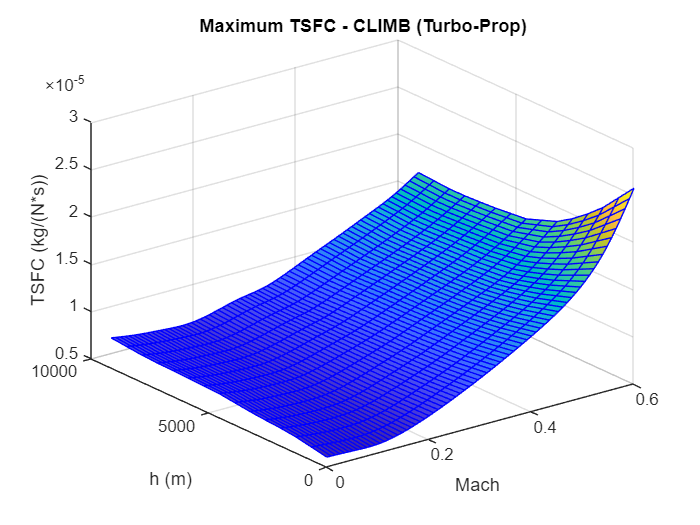

m_TSFC_Interp_CLIMB = AircraftData.Propulsion.Interp.TSFC_Interp_CLIMB; % original data in lb/(lbf*hr)

mm_TSFC_SI_CLIMB = interp2( ...
    m_M_CLIMB, m_h_ft_CLIMB, AircraftData.Propulsion.tsfc2SI*m_TSFC_Interp_CLIMB, ...
    mm_M_CLIMB, mm_h_ft_CLIMB, 'bilinear');

figure
s_TSFC_SI_CLIMB = mesh(mm_M_CLIMB, convlength(mm_h_ft_CLIMB,'ft','m'), mm_TSFC_SI_CLIMB, 'EdgeColor', 'blue');
s_TSFC_SI_CLIMB.FaceColor = 'interp';
title('Maximum TSFC - CLIMB (Turbo-Prop)')
xlabel('Mach'); ylabel('h (m)'); zlabel('TSFC (kg/(N*s))') 

#### CRUISE

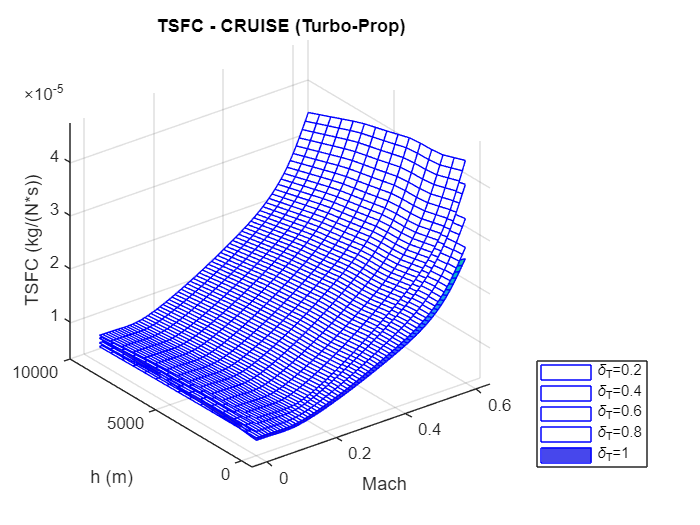

m_TSFC_CRUISE = AircraftData.Propulsion.Interp.TSFC_Interp_CRUISE;

mm_TSFC_CRUISE = interpn( ...
    m_throttle_CRUISE, m_M_CRUISE, m_h_ft_CRUISE, AircraftData.Propulsion.tsfc2SI*m_TSFC_CRUISE, ...
    mm_throttle_CRUISE, mm_M_CRUISE, mm_h_ft_CRUISE, 'bilinear');

figure
s_TSFC_CRUISE = mesh( ...
    squeeze(mm_M_CRUISE(1,:,:)), ...
    squeeze(convlength(mm_h_ft_CRUISE(1,:,:),'ft','m')), ...
    squeeze(mm_TSFC_CRUISE(1,:,:)), ...
    'EdgeColor', 'blue');
hold on
lbls_legend{1} = sprintf('\\delta_T=%s',num2str(vv_throttle_Thrust_CRUISE(1)));
for kThr=2:length(vv_throttle_Thrust_CRUISE)
    lbls_legend{kThr} = sprintf('\\delta_T=%s',num2str(vv_throttle_Thrust_CRUISE(kThr)));
    s_TSFC_CRUISE = mesh( ...
        squeeze(mm_M_CRUISE(kThr,:,:)), ...
        squeeze(convlength(mm_h_ft_CRUISE(kThr,:,:),'ft','m')), ...
        squeeze(mm_TSFC_CRUISE(kThr,:,:)), ...
        'EdgeColor', 'blue');
end

legend(lbls_legend,'Location','southeastoutside')

s_TSFC_CRUISE.FaceColor = 'interp';
title(['TSFC - CRUISE (Turbo-Prop)'])
xlabel('Mach'); ylabel('h (m)'); zlabel('TSFC (kg/(N*s))') 
axis padded
hold off